% Código que calcula en coeficiente de similitud DICE 
% entre dos segmentaciones de imágenes cerebrales

clear all
OriginalImage = niftiread("sub-101_ses-BL_T1w.nii");% Carga de los archivos: volúmenes del cerebro de free

GrayFSL= niftiread("grey-101-FSL.nii");% Segmentación de materia gris FSL
WhiteFSL = niftiread("white-101-FSL.nii");% Segmentación de materia blanca FSL

GrayFSurfer = niftiread("grey-101-FSurfer.nii");% Segmentación de materia gris FreeSurfer
WhiteFSurfer = niftiread("white-101-FSurfer.nii");% Segmentación de materia blanca FreeSurfer


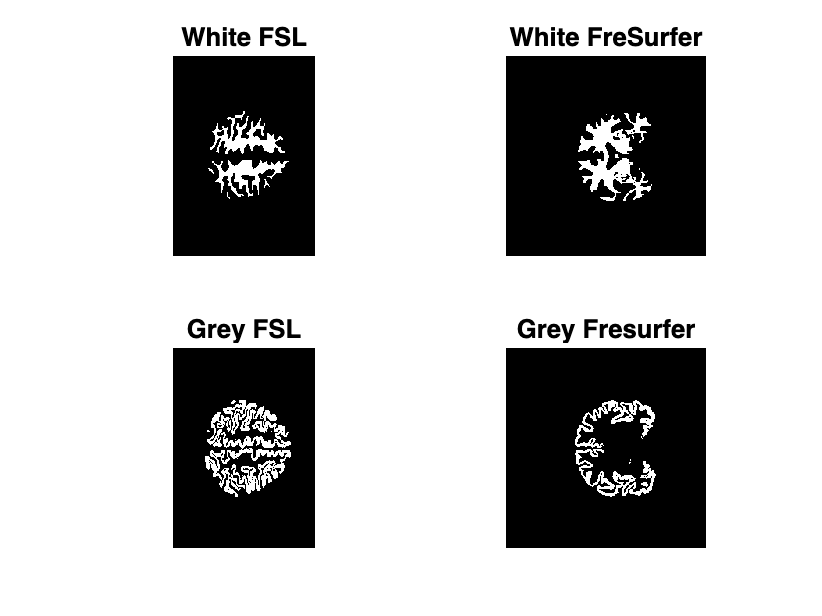

% Selección de los labels de materia blanca y labels de materia gris.

cwFreeSurf = WhiteFSurfer >= 72;
cgFreeSurf = GrayFSurfer >= 11101;      

cwfsl = WhiteFSL > 0;
cgfsl = GrayFSL > 0.3;

figure
subplot(2,2,1)
imshow(cwfsl(:,:,150),[]);
title('White FSL') 
subplot(2,2,2)  
imshow(cwFreeSurf(:,:,150),[]);
title('White FreSurfer') 
subplot(2,2,3)
imshow(cgfsl(:,:,150),[]);
title('Grey FSL') 
subplot(2,2,4)  
imshow(cgFreeSurf(:,:,150),[]);
title('Grey Fresurfer') 

% Se ajustajn las coordenadas que abarcan las imágenes de ambas
% segmentaciones para que las dos contengan el mismo espacio en cm.

Wh_FreSurf = cwFreeSurf(16:241,7:251,31:225);
Gr_FreSurf = cgFreeSurf(16:241,7:251,31:225);

Wh_FSL = (cwfsl(1:256,1:182,1:256));
Gr_FSL = (cgfsl(1:256,1:182,1:256));

% Ajustar el tamaño a 256x256x256 para que las imágenes coincidan

Rsize_Wh_FreSurf = imresize3(Wh_FreSurf,[256, 256, 256]);
Rsize_Gr_FreSurf = imresize3(Gr_FreSurf,[256, 256, 256]);

Rsize_Wh_FSL = imresize3(Wh_FSL,[256, 256, 256]);
Rsize_Gr_FSL = imresize3(Gr_FSL,[256, 256, 256]);

% Permutar columnas ya que tienen volteados los ejes y y z
Resicwfsl = permute(Rsize_Wh_FSL,[1 3 2]);
Resicgfsl = permute(Rsize_Gr_FSL,[1 3 2]);

% Reflejar y rotar las imágenes 

FinalwhiteFreesurf = flip(imrotate(Rsize_Wh_FreSurf,-90),2);
FinalgreyFresurf = flip(imrotate(Rsize_Gr_FreSurf,-90),2);

FinalwhiteFSL = imrotate(Resicwfsl,90);
FinalgreyFSL = imrotate(Resicgfsl,90);


% Resultados 

% DICE
diceResult_White_101 = dice(FinalwhiteFreesurf,FinalwhiteFSL)

diceResult_White_101 = 0.7024

diceResult_Grey_101 = dice(FinalgreyFresurf,FinalgreyFSL)

diceResult_Grey_101 = 0.5822


% Mostrar ejemplo de una slice
n = 130

n = 130

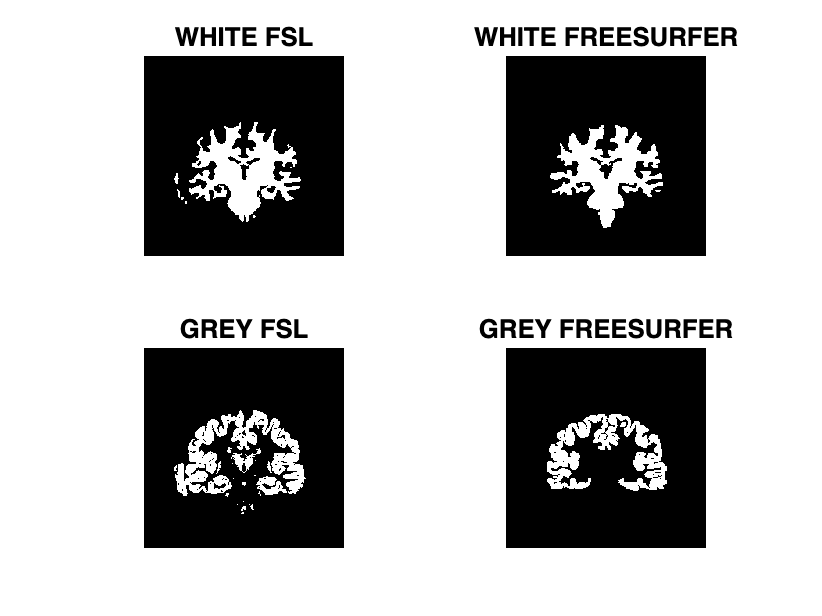

figure
subplot(2,2,1)
imshow(FinalwhiteFSL(:,:,n), []);
title('WHITE FSL')

subplot(2,2,2)  
imshow(FinalwhiteFreesurf(:,:,n),[]);
title('WHITE FREESURFER') 

subplot(2,2,3)
imshow(FinalgreyFSL(:,:,n), []);
title('GREY FSL') 

subplot(2,2,4)  
imshow(FinalgreyFresurf(:,:,n),[]);
title('GREY FREESURFER') 